# Aircraft Conflict Resolution

syms t x_circle y_circle
clear length


protected_zone = 2.5;    % zone of protection
v = 5;
omega = 1;
phi = pi/2;
init_state = [15; -15];

v1 = v;
v2 = v;
omega_1 = omega;
omega_2 = omega;

safe_radius = protected_zone*2; % used for encode the protected radius aroudn the second aircraft
r_turn = v/omega;       % turning radius
v_slope =v2/v1;        % slope of velocity seen from relative system

## State q1: cruise

% state q1: velocity
x_r_dot_q1 = -v1 + v2*cos(phi);
y_r_dot_q1 = v2*sin(phi);
phi_r_dot_q1 = 0;

state_q1_dot = [x_r_dot_q1; y_r_dot_q1];
%state q1: position
x_r_q1 = int(x_r_dot_q1, t) + init_state(1);
y_r_q1 = int(y_r_dot_q1, t) + init_state(2);
phi_r = rad2deg(atan( y_r_dot_q1 / x_r_dot_q1));

state_q1 = [x_r_q1; y_r_q1]

$$state\_q1 = \left(\begin{array}{c} 15-5\,t\\ -15+5\,t \end{array}\right)$$

## State q2: manuver

% solutions of given differential equation
x_r_q2 = +5 * cos(t) + 5 * sin(t) + 5;
y_r_q2 = +5 * cos(t) - 5 * sin(t) + 5;

state_q2 = [x_r_q2; y_r_q2];

x_r_dot_q2 = -5 + omega_1*y_r_q2;
y_r_dot_q2 = 5 - omega_1*x_r_q2;

state_q2_dot = [x_r_dot_q2; y_r_dot_q2]

$$state\_q2\_dot = \left(\begin{array}{c} 5\,\cos\left(t\right)-5\,\sin\left(t\right)\\ -5\,\cos\left(t\right)-5\,\sin\left(t\right) \end{array}\right)$$

fprintf("x_r_dot_q2 - diff(x_r_q2, t) == %f ", simplify(x_r_dot_q2 - diff(x_r_q2, t) ) )

x_r_dot_q2 - diff(x_r_q2, t) == 0.000000 

fprintf("y_r_dot_q2 - diff(y_r_q2, t) == %f ", simplify(y_r_dot_q2 - diff(y_r_q2, t) ) )

y_r_dot_q2 - diff(y_r_q2, t) == 0.000000 

## Check for possibile collision

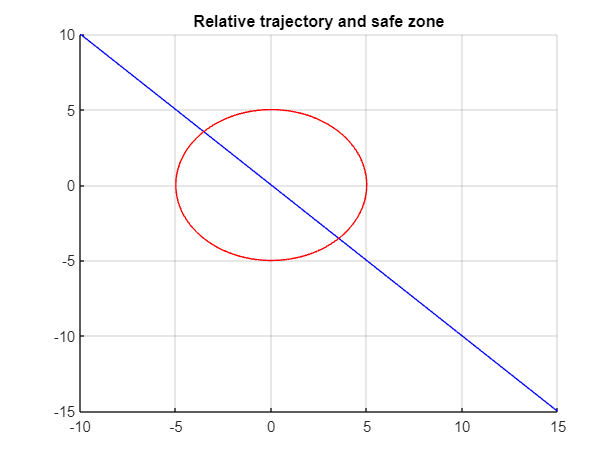

circle_eqn = safe_radius*[cos(t);sin(t)];

t_s = linspace(0, 5, 100);          % linspace for straight
t_q1 = linspace(0, 2*pi, 100);      % linespace for the circle

state_q1_x_vals = double( subs(state_q1(1), t, t_s) );  
state_q1_y_vals = double( subs(state_q1(2), t, t_s) );

circle_x_vals = subs( circle_eqn(1), t, t_q1 );
circle_y_vals = subs( circle_eqn(2), t, t_q1 );
 
figure;
hold on;
grid on;
title('Relative trajectory and safe zone')
plot(state_q1_x_vals, state_q1_y_vals, 'b')
plot(circle_x_vals, circle_y_vals, 'r')

eqn_circle_break = state_q1(1)^2 + state_q1(2)^2 - safe_radius^2;

time_break = solve(eqn_circle_break, t);    

% calculating intersection points with the circle: lowest one represent the
% collision between aircraft
x1_break = double( subs(state_q1(1), t, time_break(1)) );
y1_break = double( subs(state_q1(2), t, time_break(1)) );
x2_break = double( subs(state_q1(1), t, time_break(2)) );
y2_break = double( subs(state_q1(2), t, time_break(2)) );

fprintf('t1 = %.2f seconds, point: (%.2f, %.2f) miles: time for collision\n', time_break(1), x1_break, y1_break);

t1 = 2.29 seconds, point: (3.54, -3.54) miles: time for collision


fprintf('t2 = %.2f seconds, point: (%.2f, %.2f) miles\n', time_break(2), x2_break, y2_break);

t2 = 3.71 seconds, point: (-3.54, 3.54) miles


## Plot of zones

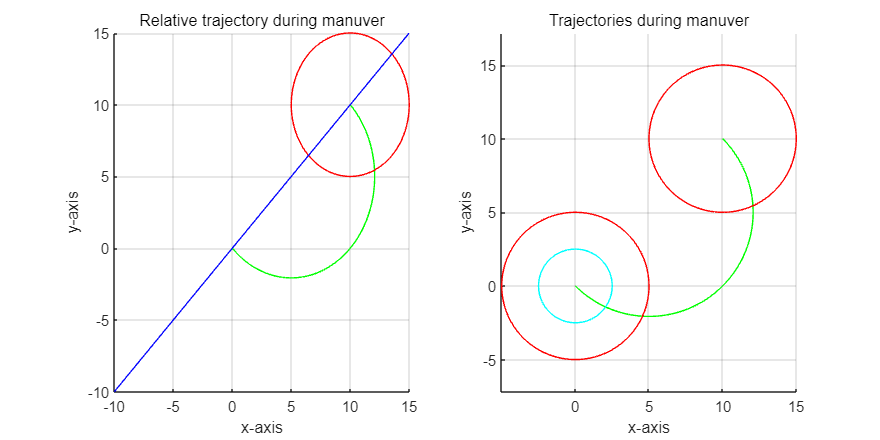

figure1=figure('Position', [100, 100, 800, 400]);

t_man = linspace(0, pi/omega, 1000);          % linespace for manuver
t_circle = linspace(0, 2*pi, 1000);     % linespace for draw cicles

% Rotation angle and rotation matrix: used for personal debug's purpose
theta = 0; % -pi/2;
rot = [cos(theta), -sin(theta); sin(theta), cos(theta)];

% rotation between state q1 and state q2
theta_12 = pi/2; 
rot_12 = [cos(theta_12), -sin(theta_12); sin(theta_12), cos(theta_12)];

% Solutions of differential equations
x_r_vals = -5 * cos(t_man*omega) + 5 * sin(t_man*omega) + 5;
y_r_vals = -5 * cos(t_man*omega) - 5 * sin(t_man*omega) + 5;

%x_r_vals = 5 * cos(t_man*omega) + 5 * sin(t_man*omega) + 5;
%y_r_vals = 5 * cos(t_man*omega) - 5 * sin(t_man*omega) + 5;

% Take the value in t=pi, which correspond the the position of the start of
% the manuever
start_manuver_x = x_r_vals( length(x_r_vals) ); % 1
start_manuver_y = y_r_vals( length(y_r_vals) ); % 1

circle_x = start_manuver_x + safe_radius*cos(t_circle);
circle_y = start_manuver_y + safe_radius*sin(t_circle);


% Rotated points
rotated_points = rot * [x_r_vals; y_r_vals];
rotated_circle = rot * [circle_x; circle_y;];
rotated_straight = rot_12* [state_q1_x_vals; state_q1_y_vals];

% First plot
subplot(1,2,1);
subtitle('Relative trajectory during manuver');
xlabel('x-axis');
ylabel('y-axis');
hold on;
grid on;
plot(rotated_points(1, :), rotated_points(2, :), 'g');
plot(rotated_circle(1,:) , rotated_circle(2,:) , 'r');
plot(rotated_straight(1,:) , rotated_straight(2,:), 'b')


% Second plot
subplot(1, 2, 2);
hold on;
plot(rotated_points(1, :), rotated_points(2, :), 'g');
plot(rotated_circle(1, :), rotated_circle(2, :), 'r');

multi_traj = []; %[0, pi/2, pi, 3*pi/2 2*pi];

for i=1:length(multi_traj) %2*pi
    safe_x_r_vals = x_r_vals + safe_radius*cos(multi_traj(i));
    safe_y_r_vals = y_r_vals + safe_radius*sin(multi_traj(i));

    rotated_safe = rot*[safe_x_r_vals; safe_y_r_vals];

    plot(rotated_safe(1,:) , rotated_safe(2,:) , 'g');
    
end

safe_circle_x = safe_radius * cos(t_circle);
safe_circle_y = safe_radius * sin(t_circle);
protected_circle_x = protected_zone * cos(t_circle);
protected_circle_y = protected_zone * sin(t_circle);

rotated_c_safe = rot * [safe_circle_x; safe_circle_y];
rotated_c_protected = rot * [protected_circle_x; protected_circle_y];

plot(rotated_c_safe(1, :), rotated_c_safe(2, :), 'r');
plot(rotated_circle(1,:) , rotated_circle(2,:) , 'r');
plot(rotated_c_protected(1,:), rotated_c_protected(2,:), 'c');

subtitle('Trajectories during manuver');
xlabel('x-axis');
ylabel('y-axis');
grid on;
axis equal;
hold off;

## 1D plot of solutions

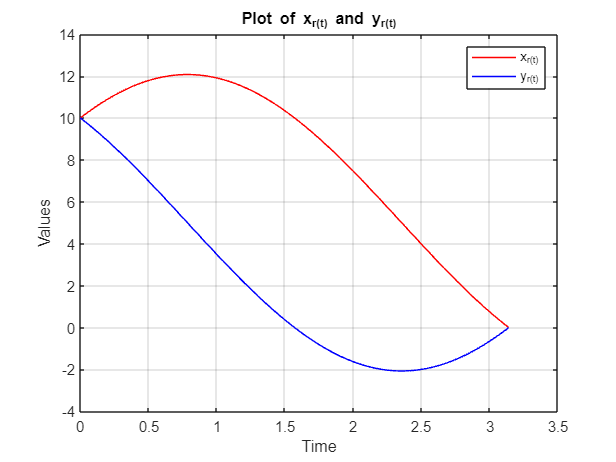

t_man = linspace(0, pi/omega, 100); % 100 points between 0 and pi

% Define the parametric equations
x_r_vals = 5 * cos(t_man*omega) + 5 * sin(t_man*omega) + 5;
y_r_vals = 5 * cos(t_man*omega) - 5 * sin(t_man*omega) + 5;

% Plot the parametric equations
figure;
plot(t_man, x_r_vals, 'r', 'LineWidth', 1); % Plot x_r_vals in red
hold on;
plot(t_man, y_r_vals, 'b', 'LineWidth', 1); % Plot y_r_vals in blue
hold off;

% Add labels and title
xlabel('Time');
ylabel('Values');
title('Plot of x_r(t) and y_r(t)');
legend('x_r(t)', 'y_r(t)');

% Show grid
grid on;

## Compute time starting manuvers

eqn_circle_start = ( state_q1(1) - start_manuver_x)^2 + (state_q1(2) + start_manuver_y)^2 - safe_radius^2;

time_man = solve(eqn_circle_start, t);

x1 = double( subs(state_q1(1), t, time_man(1)) );
y1 = double( subs(state_q1(2), t, time_man(1)) );
x2 = double( subs(state_q1(1), t, time_man(2)) );
y2 = double( subs(state_q1(2), t, time_man(2)) );

fprintf('t1 = %.2f seconds, point: (%.2f, %.2f) miles\n', time_man(1), x1, y1);

t1 = 0.29 seconds, point: (13.54, -13.54) miles


fprintf('t2 = %.2f seconds, point: (%.2f, %.2f) miles\n', time_man(2), x2, y2);

t2 = 1.71 seconds, point: (6.46, -6.46) miles


## Result

fprintf("INITIAL RELATIVE POSITION: (%.2f, %.2f)", init_state(1), init_state(2)) 

INITIAL RELATIVE POSITION: (15.00, -15.00)

fprintf("MANUVER DISABLE for t < %.2f seconds \t\t-> Aircraft 2 is to too far from Aircraft 1, manuver will be useless", time_man(2))

MANUVER DISABLE for t < 1.71 seconds 		-> Aircraft 2 is to too far from Aircraft 1, manuver will be useless

fprintf("MANUVER ENABLED for %.2f <= t < %.2f seconds \t-> Aircraft 1 and 2 can perfom manuver succesully avoiding collisions", time_man(2), time_break(1))

MANUVER ENABLED for 1.71 <= t < 2.29 seconds 	-> Aircraft 1 and 2 can perfom manuver succesully avoiding collisions

fprintf("MANUVER FORCED for t = %.2f seconds\t\t-> Aircrafts must perform manuver or they will collide", time_break(1))

MANUVER FORCED for t = 2.29 seconds		-> Aircrafts must perform manuver or they will collide